Ts = 0.01;
% m = 0.217;
% l = 0.240;
m = 0.1401;
l = 0.0307;
g = 9.81;
I_cfRod = 0.0000060512;

I_tot_init = 0.003;
c1_init = 0.001;
c2_init = 0;

% load("knownMassTest.mat");     % Load in timestamp & orientation data for only the free swinging motion
% [y,tVec] = resample(data(:,2)*(pi()/180), data(:,1)-data(1:1), 1/Ts);  % Resample data to ensure consistent fixed timesteps

data = iddata(y,[],Ts,"Name","SwingTest");
data.OutputName = "theta";
data.OutputUnit = "rad";
data.Tstart = 0;
data.TimeUnit = 's';

sysnl = idnlgrey('nl_greybox_ss', [1 0 2], {I_tot_init, c1_init, c2_init, m, g, l});
sysnl.Parameters(1).Minimum = 0;            % Limit I to positive
sysnl.Parameters(2).Minimum = 0;            % Limit c1 to positive
sysnl.Parameters(3).Fixed = true;            % Limit c2 to positive
sysnl.Parameters(4).Fixed = true;           % fix m
sysnl.Parameters(5).Fixed = true;           % fix g
sysnl.Parameters(6).Fixed = true;           % fix l
sysnl.InitialStates(1).Fixed = false;       % estimate theta(0)
sysnl.InitialStates(2).Fixed = false;       % estimate dtheta(0)


opts = nlgreyestOptions('SearchMethod', 'lsqnonlin');
opts.SearchOptions.StepTolerance = 1e-15;
opts.SearchOptions.FunctionTolerance = 1e-15;
opts.SearchOptions.MaxIterations = 1000;

sysnl_est = nlgreyest(data,sysnl,opts);

format short
WhyStop = sysnl_est.Report.Termination.WhyStop

WhyStop = 'Change in cost was less than the specified tolerance.'

Iterations = sysnl_est.Report.Termination.Iterations

Iterations = 137

FitPercent = sysnl_est.Report.Fit.FitPercent

FitPercent = 93.9329


format long
I = sysnl_est.Parameters(1).Value - m*l^2 - I_cfRod

I =      3.407412189780673e-04


c1 = sysnl_est.Parameters(2).Value

c1 =      4.067484811864389e-04


c2 = sysnl_est.Parameters(3).Value/10000000

c2 =      0


theta0 = sysnl_est.InitialStates(1).Value

theta0 =   -0.107596937384941


dtheta0 = sysnl_est.InitialStates(2).Value

dtheta0 =    8.331474847719257



format bank; I_xx_gsmm = I*10^9

I_xx_gsmm =      340741.22


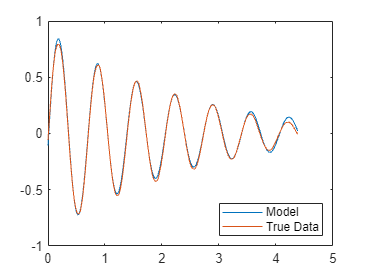



[simout,] = initial(sysnl_est,[theta0, dtheta0],tVec);
plot(tVec, simout, tVec, y)
legend("Model", "True Data","Location","southeast")